# Example: Localize using Generated Map 

Ensure that this example is run in a separate MATLAB session from the Robot Simulink Application. 

### **Background**

This example will receive LIDAR scans from the [Robot Simulink Application](matlab:open('./robot_app.slx')) (run in a separate MATLAB session), and use the map generated in the [SLAM application](matlab:open('./ex_slam.mlx')) to localize the robot. The robot's pose is sent back to the [Robot Simulink Application](matlab:open('./robot_app.slx')). 

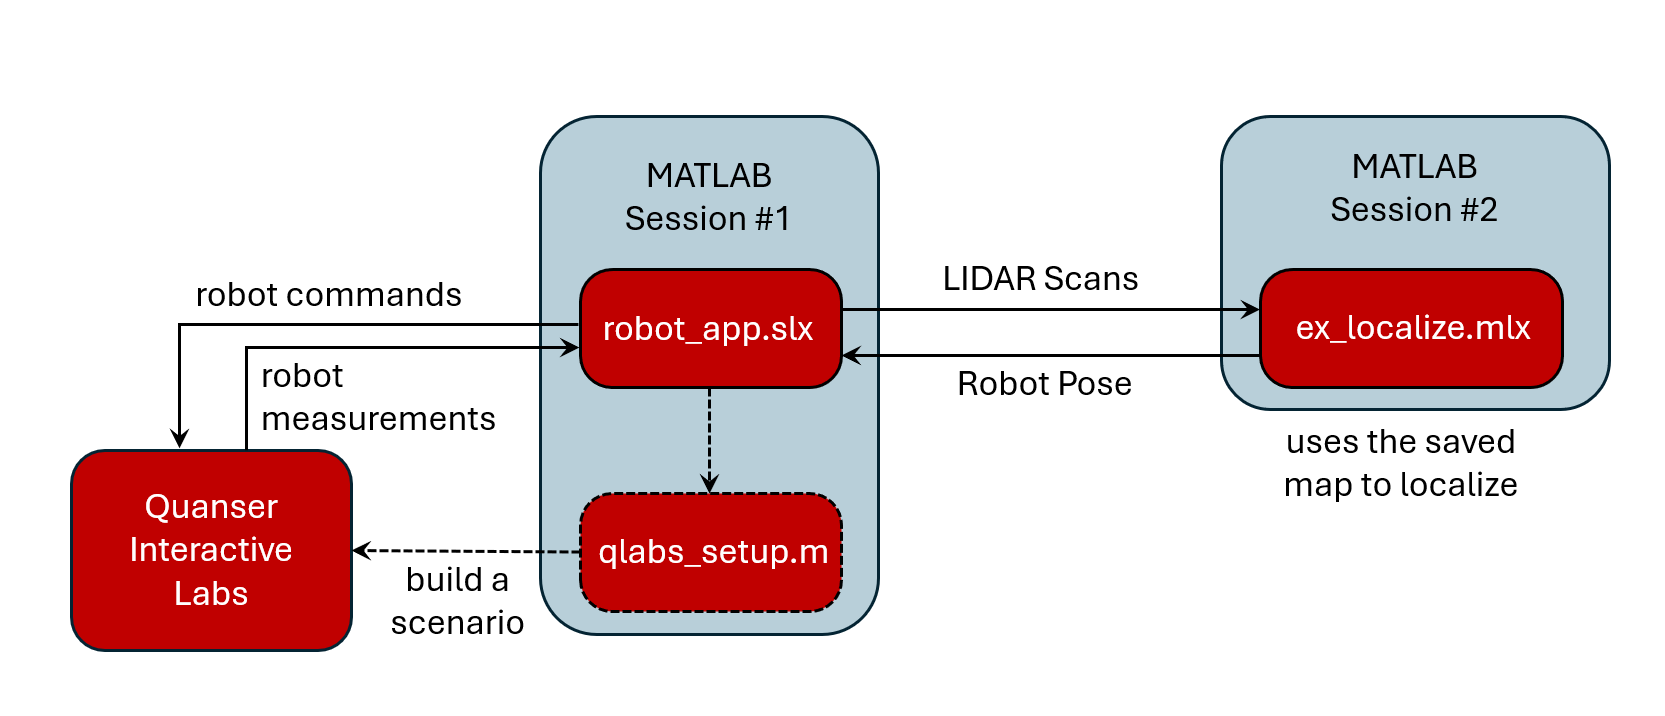

### Load the Map object

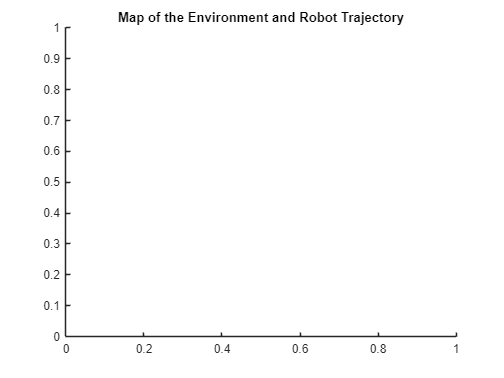

load("map.mat");

### Set up Additional Parameters

These parameters should not affect the performance of this example. 

step_size    = 0.10;         % time set 
t            = 0.0;          %
pose         = [0, 0, 0];    % initial pose estimate

### Set up Stream communications 

This sets up the stream communications (using local TCPIP) with the [Robot Simulink Application](matlab:open('./robot_app.slx')) to exchange LIDAR scans and pose data.

% Quanser's Stream API
uri       = 'tcpip://localhost:18465';
stream    = quanser.communications.stream.connect(uri, false);

### Localization Loop

The code below is placed in a try/catch to correctly close the Stream connection under any condition. Check code comments for details. 

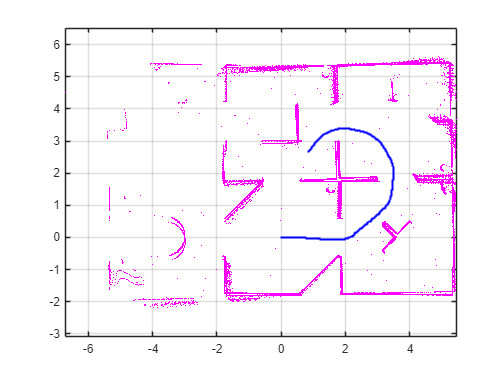


Server has closed the connection.



 Map saved, application terminating ...


Connection closed


try
    % Main loop
    while ~qc_get_key_state(27) % while Esc key not pressed  
        
        try
            % Send pose information back to Robot Simulink Application.
            stream.send_double_array(pose);
            stream.flush;
            
            % Receive Lidar data from the Robot Simulink Application
            % Note: this is a blocking stream and hence, handles timing
            value = stream.receive_double_array(420);
        catch
            fprintf(1, '\nServer has closed the connection.\n');
            break;
        end
        if isempty(value) % Simulink app was terminated...
            fprintf(1, '\nServer has closed the connection.\n');
            break;
        end

        % Create a lidarScan from the data received
        scan = lidarScan(value(1:210,1), value(211:420,1));

        % Estimate the pose from previously generated Map
        result = findPose(map, scan, [pose(1), pose(2)]);
        if ~isempty(result)
            pose(1:3) = result;
        end
        
        t = t + step_size;
    end

    % Once the Esc key is pressed, close the stream handle used for
    % communications.
    fprintf(1, '\n Esc key pressed, application terminating ...\n');

    % Close the stream connection.
    stream.close;
    fprintf(1, 'Connection closed\n');
    
catch err
    % Error handling
    fprintf(1, '\n');
    fprintf(2, '\n%s.\nShutting down the client...\n', err.message);
    stream.close;
    fprintf(1, 'Connection closed\n');
    rethrow(err);
    
end